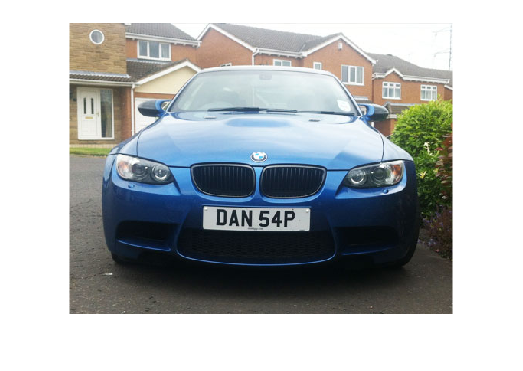

clc;
clear;
close all;
Input = imread ('car.jpg');
figure(1);
imshow(Input);

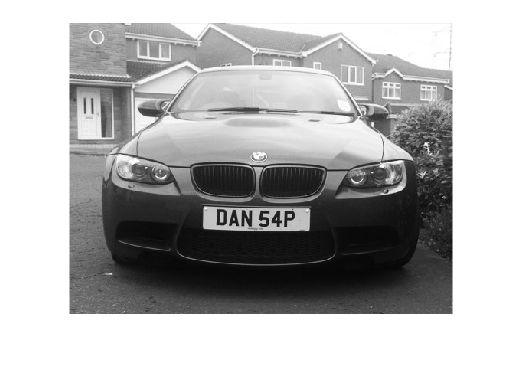

Igray = rgb2gray(Input); %(Convert an RGB Image to Gray Scale image)
[rows, cols] = size(Igray);        
Idilate = Igray; %% Dilate and Erode Image in order to remove noise
for i = 1:rows
for j = 2:cols-1
temp = max(Igray(i,j-1), Igray(i,j));
Idilate(i,j) = max(temp, Igray(i,j+1));
end
end
I = Idilate;
figure(2);
imshow(Igray);

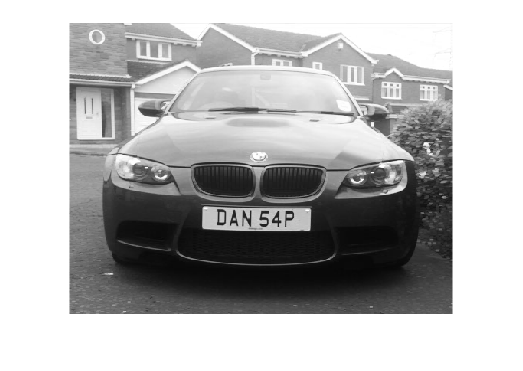

figure(3);
title('Dilated Image')
imshow(Idilate);

total_sum = 0;
%% PROCESS EDGES IN HORIZONTAL DIRECTION
max_horz = 0;
maximum = 0;
for i = 2:cols
sum = 0;
for j = 2:rows
if(I(j, i) > I(j-1, i))
difference = uint32(I(j, i) - I(j-1, i));
else
difference = uint32(I(j-1, i) - I(j, i));
end
if(difference > 20)
sum = sum + difference;
end
end
horz1(i) = sum;
% Find Peak Value
if(sum > maximum)
max_horz = i;
maximum = sum;
end
total_sum = total_sum + sum;
end
average = total_sum / cols;
figure(4);
% Plot the Histogram for analysis
subplot(3,1,1);
plot (horz1);
title('Horizontal Edge Processing Histogram');
xlabel('Column Number ->');
ylabel('Difference ->');
%% Smoothen the Horizontal Histogram by applying Low Pass Filter
sum = 0;
horz = horz1;
for i = 21:(cols-21)
sum = 0;
for j = (i-20):(i+20)
sum = sum + horz1(j);
end
horz(i) = sum / 41;
end
subplot(3,1,2)
plot (horz);
title('Histogram after passing through Low Pass Filter');
xlabel('Column Number ->');
ylabel('Difference ->');
%% Filter out Horizontal Histogram Values by applying Dynamic Threshold
disp('Filter out Horizontal Histogram...');

Filter out Horizontal Histogram...


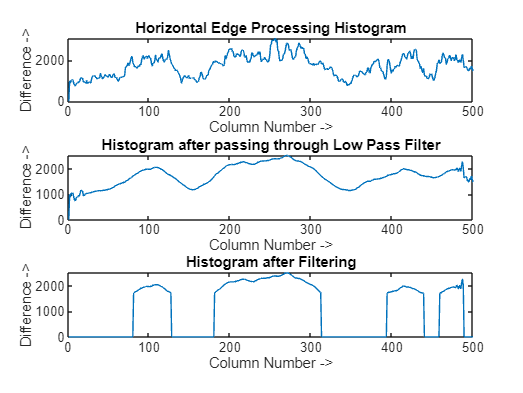

for i = 1:cols
if(horz(i) < average)
horz(i) = 0;
for j = 1:rows
I(j, i) = 0;
end
end
end
subplot(3,1,3);
plot (horz);
title('Histogram after Filtering');
xlabel('Column Number ->');
ylabel('Difference ->');

%% PROCESS EDGES IN VERTICAL DIRECTION
difference = 0;
total_sum = 0;
difference = uint32(difference);
disp('Processing Edges Vertically...');

Processing Edges Vertically...


maximum = 0;
max_vert = 0;
for i = 2:rows
sum = 0;
for j = 2:cols %cols
if(I(i, j) > I(i, j-1))
difference = uint32(I(i, j) - I(i, j-1));
end
if(I(i, j) <= I(i, j-1))
difference = uint32(I(i, j-1) - I(i, j));
end
if(difference > 20)
sum = sum + difference;
end
end
vert1(i) = sum;
%% Find Peak in Vertical Histogram
if(sum > maximum)
max_vert = i;
maximum = sum;
end
total_sum = total_sum + sum;
end
average = total_sum / rows;
figure(5)
subplot(3,1,1);
plot (vert1);
title('Vertical Edge Processing Histogram');
xlabel('Row Number ->');
ylabel('Difference ->');
%% Smoothen the Vertical Histogram by applying Low Pass Filter
disp('Passing Vertical Histogram through Low Pass Filter...');

Passing Vertical Histogram through Low Pass Filter...


sum = 0;
vert = vert1;
for i = 21:(rows-21)
sum = 0;
for j = (i-20):(i+20)
sum = sum + vert1(j);
end
vert(i) = sum / 41;
end
subplot(3,1,2);
plot (vert);
title('Histogram after passing through Low Pass Filter');
xlabel('Row Number ->');
ylabel('Difference ->');
%% Filter out Vertical Histogram Values by applying Dynamic Threshold
disp('Filter out Vertical Histogram...');

Filter out Vertical Histogram...


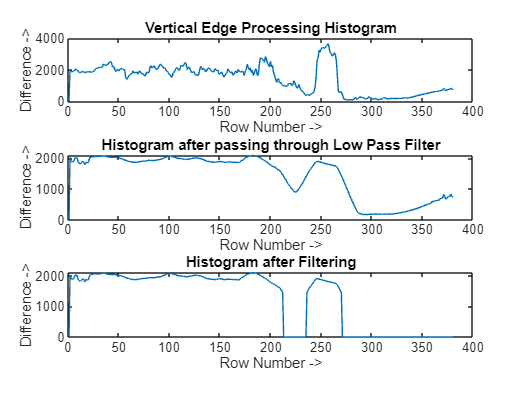

for i = 1:rows
if(vert(i) < average)
vert(i) = 0;
for j = 1:cols
I(i, j) = 0;
end
end
end
subplot(3,1,3);
plot (vert);
title('Histogram after Filtering');
xlabel('Row Number ->');
ylabel('Difference ->');

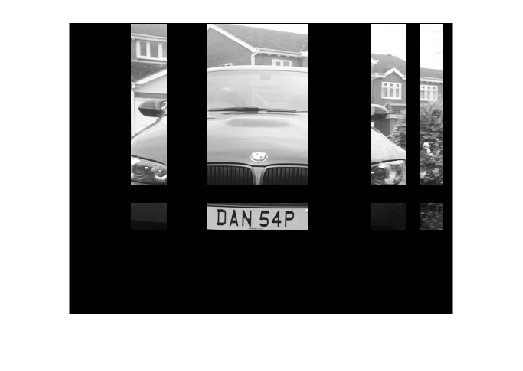

figure(6)
imshow(I)

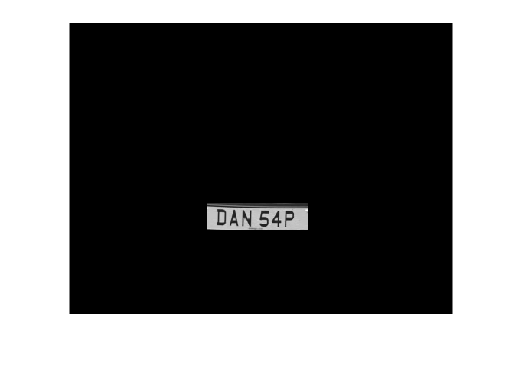

%% Find Probable candidates for Number Plate
j = 1;
for i = 2:cols-2
if(horz(i) ~= 0 && horz(i-1) == 0 && horz(i+1) == 0)
column(j) = i;
column(j+1) = i;
j = j + 2;
elseif((horz(i) ~= 0 && horz(i-1) == 0) || (horz(i) ~= 0 && horz(i+1) == 0))
column(j) = i;
j = j+1;
end
end
j = 1;
for i = 2:rows-2
if(vert(i) ~= 0 && vert(i-1) == 0 && vert(i+1) == 0)
row(j) = i;
row(j+1) = i;
j = j + 2;
elseif((vert(i) ~= 0 && vert(i-1) == 0) || (vert(i) ~= 0 && vert(i+1) == 0))
row(j) = i;
j = j+1;
end
end
[~, column_size] = size (column);
if(mod(column_size, 2))
column(column_size+1) = cols;
end
[temp row_size] = size (row);
if(mod(row_size, 2))
row(row_size+1) = rows;
end
%% Region of Interest Extraction
%Check each probable candidate
for i = 1:2:row_size
for j = 1:2:column_size
% If it is not the most probable region remove it from image
if(~((max_horz >= column(j) && max_horz <= column(j+1)) && (max_vert >=row(i) && max_vert <= row(i+1))))
%This loop is only for displaying proper output to User
for m = row(i):row(i+1)
for n = column(j):column(j+1)
I(m, n) = 0;
end
end   
end
end
end
figure(8) 
imshow(I)

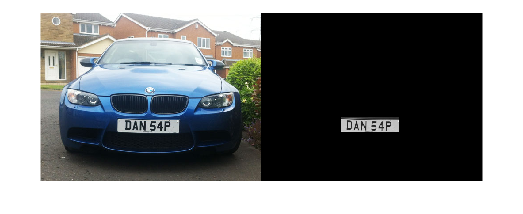

imshowpair(Input,I,'montage')

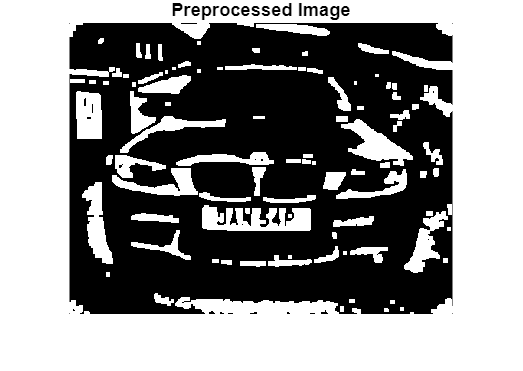

% Preprocess the image (convert to grayscale and enhance contrast)
enhancedImg = imadjust(Idilate);

% Detect edges (optional for number plate localization)
edges = edge(enhancedImg, 'Canny');
% Apply median filtering to remove small noise
filteredImg = medfilt2(enhancedImg);

% Threshold the image to segment text better
binaryImg = imbinarize(filteredImg, 'adaptive');

% Further clean up the binary image with morphological operations
se = strel('rectangle', [5, 5]); % Structural element for morphological filtering
cleanedImg = imopen(binaryImg, se);
imshow(cleanedImg); title('Preprocessed Image');


% Perform OCR to extract text from the image
results = ocr(enhancedImg);
platenumber = strtrim(results.Text);
platenumber=string(platenumber);
platenumber = regexprep(platenumber, '[^a-zA-Z0-9]','');
% Display the detected text
disp(['Detected Plate Number: ',platenumber]);

    "Detected Plate Number: "    "DAN54P"



 % Clean up whitespace

javaaddpath('C:\Users\SHREYASI PRADHAN\mysql-connector-j-9.1.0.jar\mysql-connector-j-9.1.0.jar');
% Create the JDBC URL
jdbcUrl = 'jdbc:mysql://localhost:3306/carowner';

% Connect to MySQL database directly with username and password
conn = database('carowner', 'root', 'mum2004@gmail.com')

conn =   connection with properties:

                  DataSource: 'carowner'
                    UserName: 'root'
                      Driver: 'com.mysql.cj.jdbc.Driver'
                         URL: 'jdbc:mysql://localhost:33 ...'
                     Message: ''
                        Type: 'JDBC Connection Object'
  Database Properties:

                  AutoCommit: 'on'
                    ReadOnly: 'off'
                LoginTimeout: 0
      MaxDatabaseConnections: 0

  Catalog and Schema Information:

              DefaultCatalog: 'carowner'
                    Catalogs: {'amitdb', 'carowner', 'information_schema' ... and 3 more}
                     Schemas: {}

  Database and Driver Information:

         DatabaseProductName: 'MySQL'
      DatabaseProductVersion: '8.0.40'
                  DriverName: 'MySQL Connector/J'
               DriverVersion: 'mysql-connector-j-9.1.0 ( ...'



% Check if connection is successful
if isopen(conn)
    disp('Connected successfully!');
else
    disp('Connection failed:');
    disp(conn.Message);
end

Connected successfully!




% Query to fetch data from the 'owner' table
query = sprintf("SELECT * FROM owner where platenumber='%s';",platenumber);

% Fetch data from database
ownerData = fetch(conn, query);

% Process the query results
if ~isempty(ownerData)
    disp('Owner details found:');
    disp(ownerData);

    % Extract owner details
    ownerName = ownerData{1, 'ownername'}; % Replace with your database's column name
    contactInfo = ownerData{1, 'phoneNumber'}; % Replace with your database's column name
    disp(['ownername: ', ownerName]);
    disp(['phoneNumber: ', contactInfo]);
else
    disp(['No owner found for plate number: ', platenumber]);
end

Owner details found:


    platenumber     ownername      phoneNumber  
    ___________    ___________    ______________

    {'DAN54P'}     {'Darshan'}    {'9902040332'}



    {'ownername: '}    {'Darshan'}



    {'phoneNumber: '}    {'9902040332'}




% Close database connection
close(conn);
disp('Database connection closed.');

Database connection closed.
